Skills Class Signal & Image Processing – Convolution and

filtering

Question 3.1

load('dataset3.mat')

b = [1/3, 1/3, 1/3];
a=1;

y=filter(b,a,xs)

y =     0.0398    0.1151   -0.0072   -0.1511   -0.2136   -0.0567    0.1077    0.0693    0.1906    0.1849    0.2825    0.0656    0.1149    0.2042    0.3830    0.3721    0.3537    0.3786    0.4566    0.4823    0.4677    0.4259    0.3459    0.4064    0.4424    0.5711    0.5658    0.5547    0.6062    0.6433    0.6909    0.7100    0.7587    0.8249    0.8260    0.7729    0.6320    0.4987    0.4942    0.3582    0.3712    0.4283    0.7605    0.8209    0.7655    0.6900    0.7360    0.8485    0.8081    0.7667


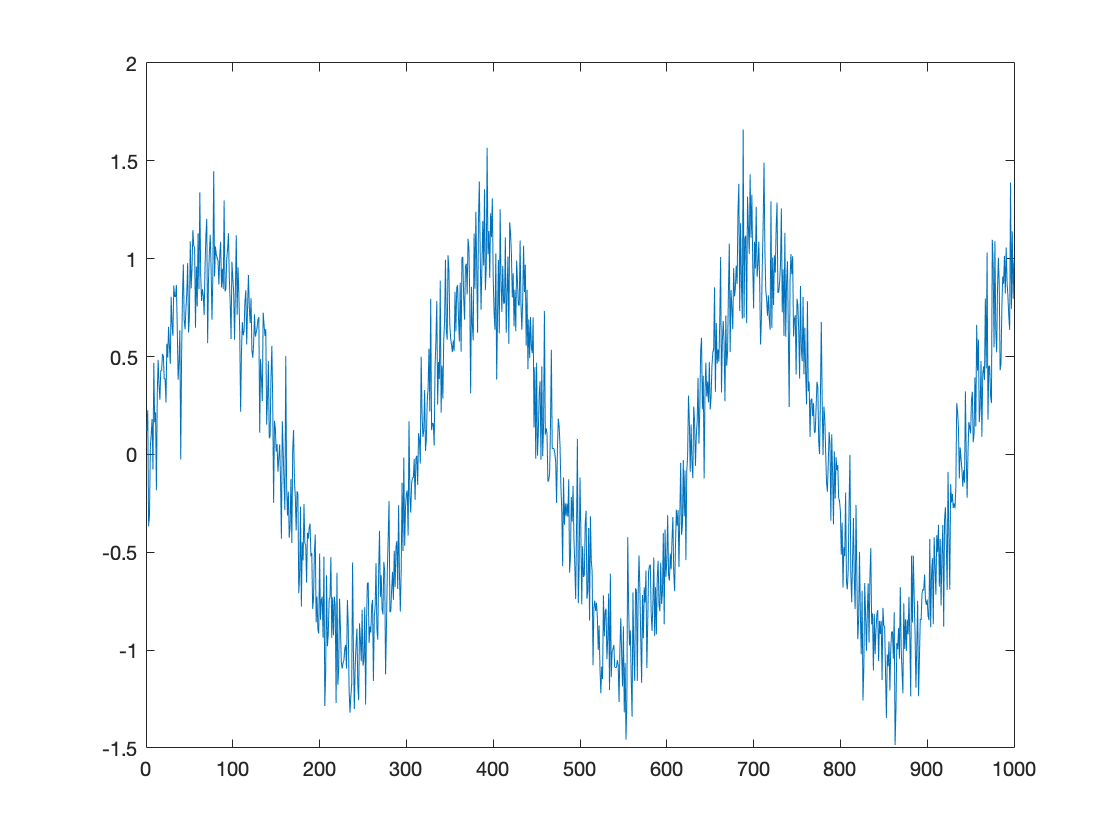


%fs - must be given in an excercise
% t = 0:1/fs:length(xs)-1;
plot(xs)

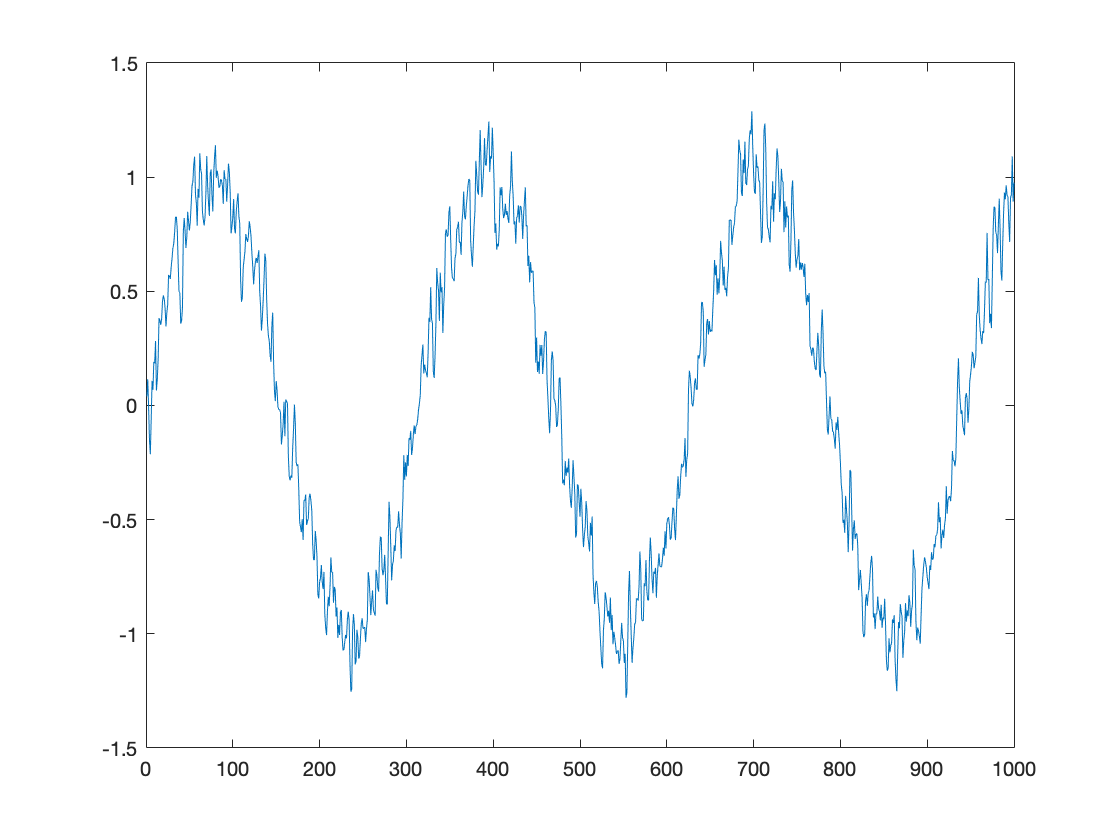

plot(y)


%plot(b,y)
%legend('Input Data','Filtered Data')


Question 3.2

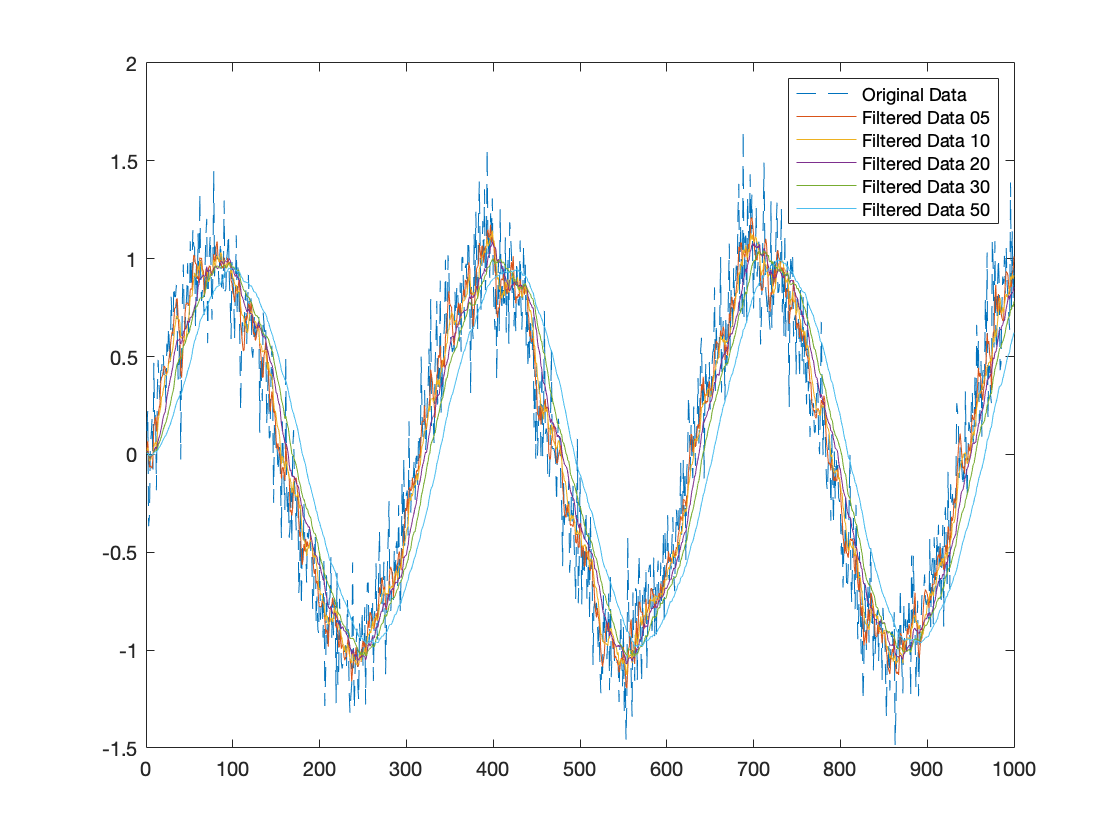

%b2 = [1/3, 1/3, 1/3];
% b5=1/5+zeros(1,5);
% b10=1/10+zeros(1,10);
% b20=1/20+zeros(1,20);
% b30=1/30+zeros(1,30);
% b50=1/50+zeros(1,50);

b5=1/5*ones(1,5);
b10=1/10*ones(1,10);
b20=1/20*ones(1,20);
b30=1/30*ones(1,30);
b50=1/50*ones(1,50);

y5=filter(b5,a,xs);
y10=filter(b10,a,xs);
y20=filter(b20,a,xs);
y30=filter(b30,a,xs);
y50=filter(b50,a,xs);

t = 1:length(xs);
plot(t,xs,'--',t,y5,'-',t,y10,'-',t,y20,'-',t,y30,'-',t,y50,'-')
legend('Original Data','Filtered Data 05','Filtered Data 10','Filtered Data 20','Filtered Data 30','Filtered Data 50')

%Response: 2 issues can be observed. First one is the biggest the length of
%moving average filter is the smoother data becomes. However with incresing
%length of moving average filter we also increase a shift of the data and
%manipulate with our data

%fs - must be given in an excercise
% t = 0:1/fs:length(xs)-1;
%larger th ewindow the less the noise, more we average out the more noise is reduced
%mean->0
%eventually shape is more distorted
% figure
% plot(t,y5)
% plot(t,y10)
% plot(t,y20)
% plot(t,y30)
% plot(t,y50)

Question 3.3

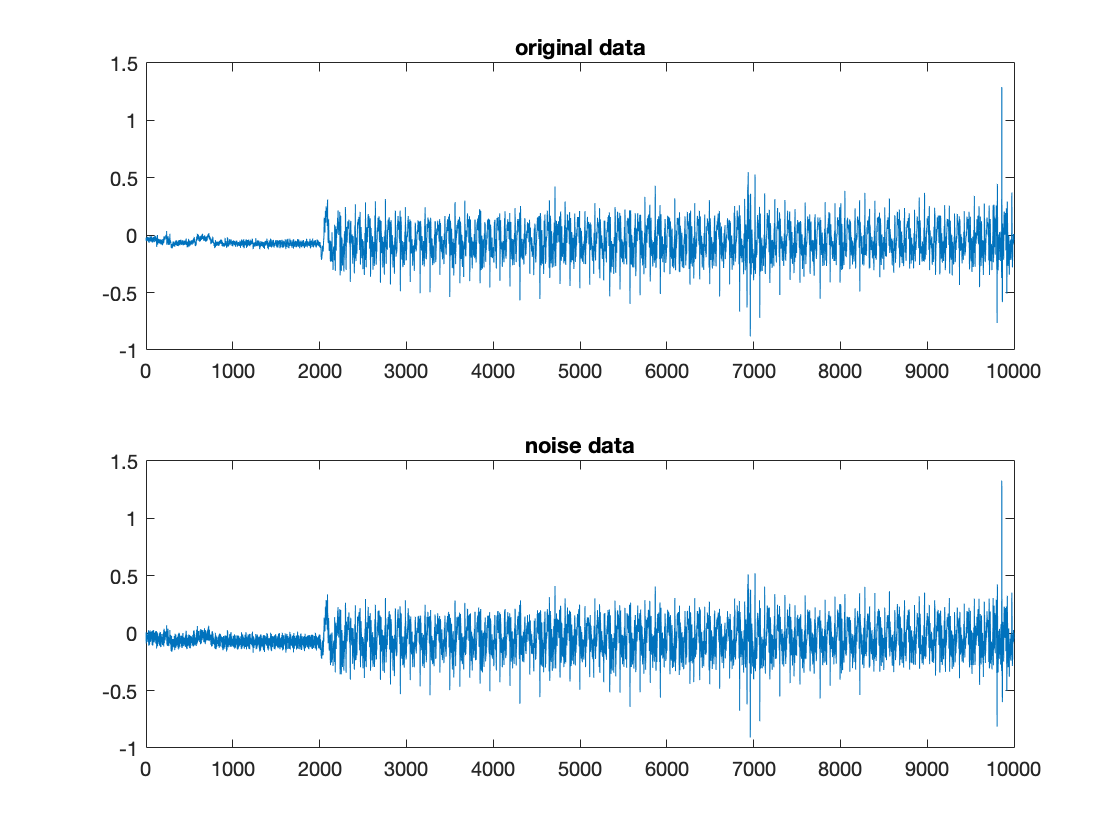

clear
load('data.mat')

figure(1);
subplot(211)
plot(data)
title('original data')

subplot(212)
plot(d1)
title('noise data')

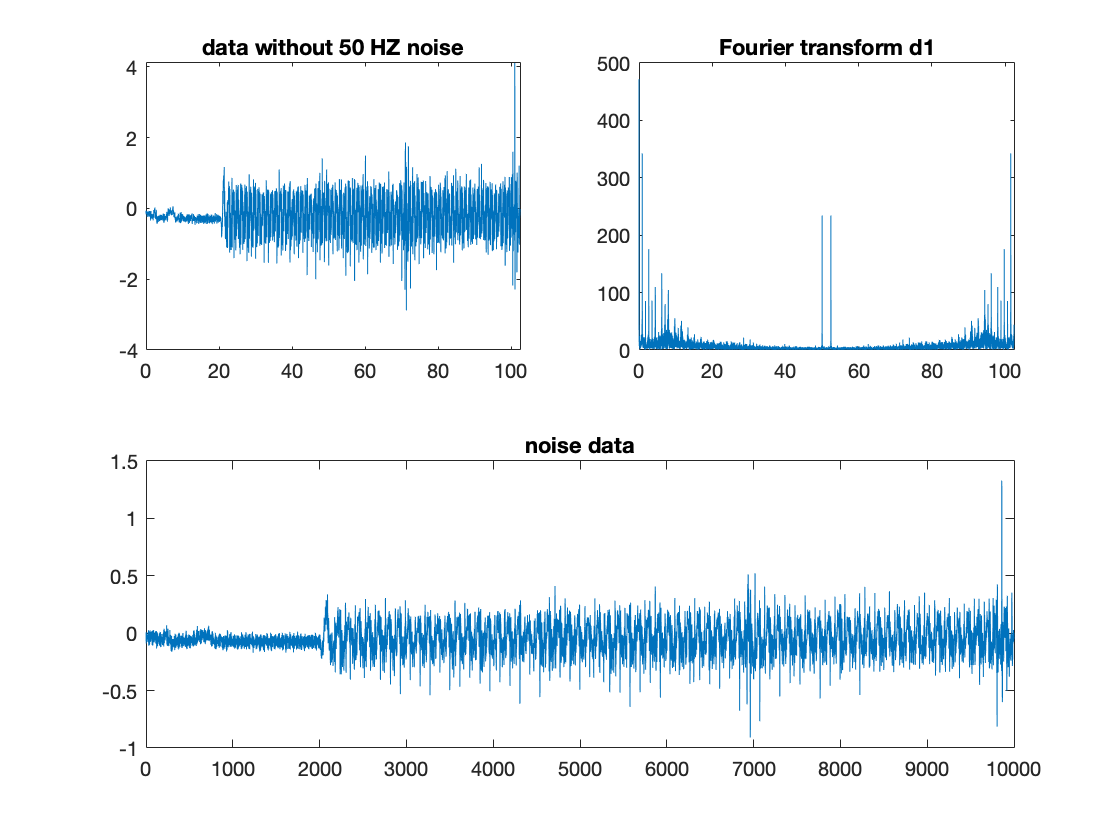


x=d1;
fs=102.4;
f=50;

%calculate normalised frequency
nf=f/fs;
omega=2*pi*nf;

z1=exp(1i*omega);
z2=exp(-1i*omega);

a=1;
b=[1,-(z1+z2),z1*z2];

y=filter(b,a,x);
x_fourier=fft(x);
y_fourier=fft(y);
%t = (0:length(y)-1)/fs;

f = (0:length(x_fourier)-1)*fs/length(x_fourier);

figure(2);

subplot(221)
plot(f,y) 
title('data without 50 HZ noise')

subplot(222)
plot(f, abs(x_fourier))
title('Fourier transform d1')

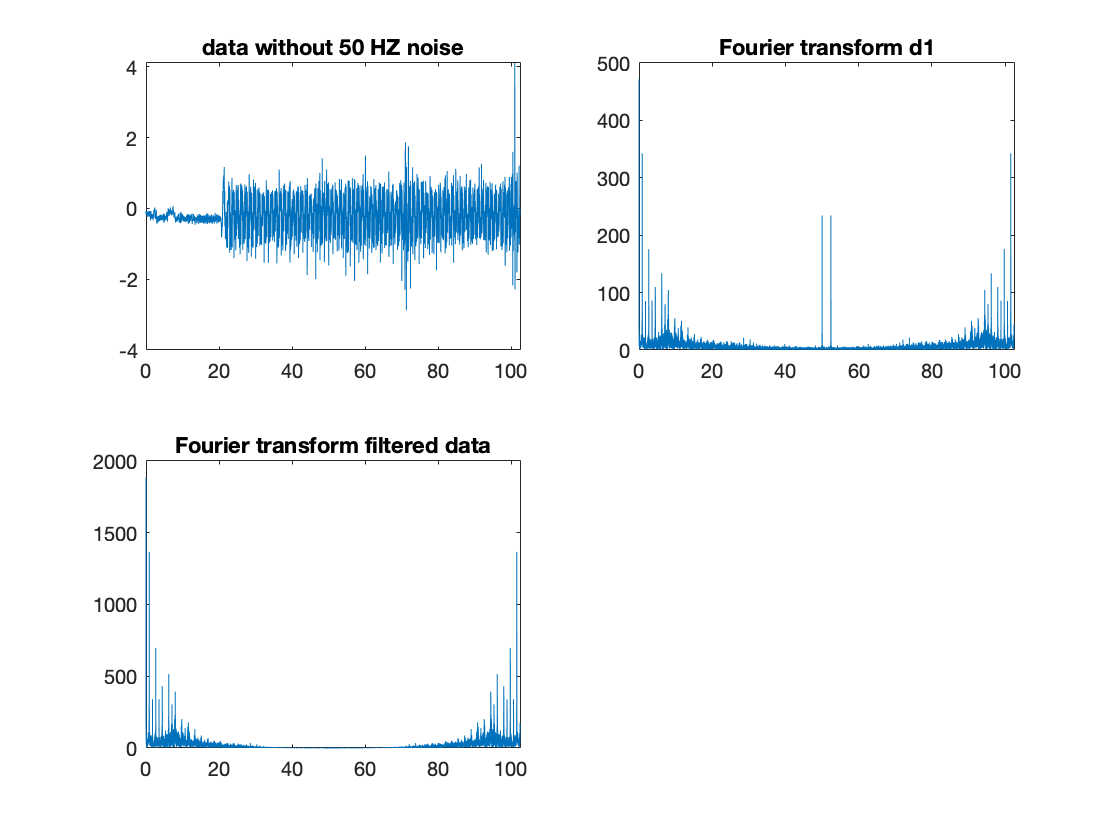


subplot(223)
plot(f, abs(y_fourier))
title('Fourier transform filtered data')

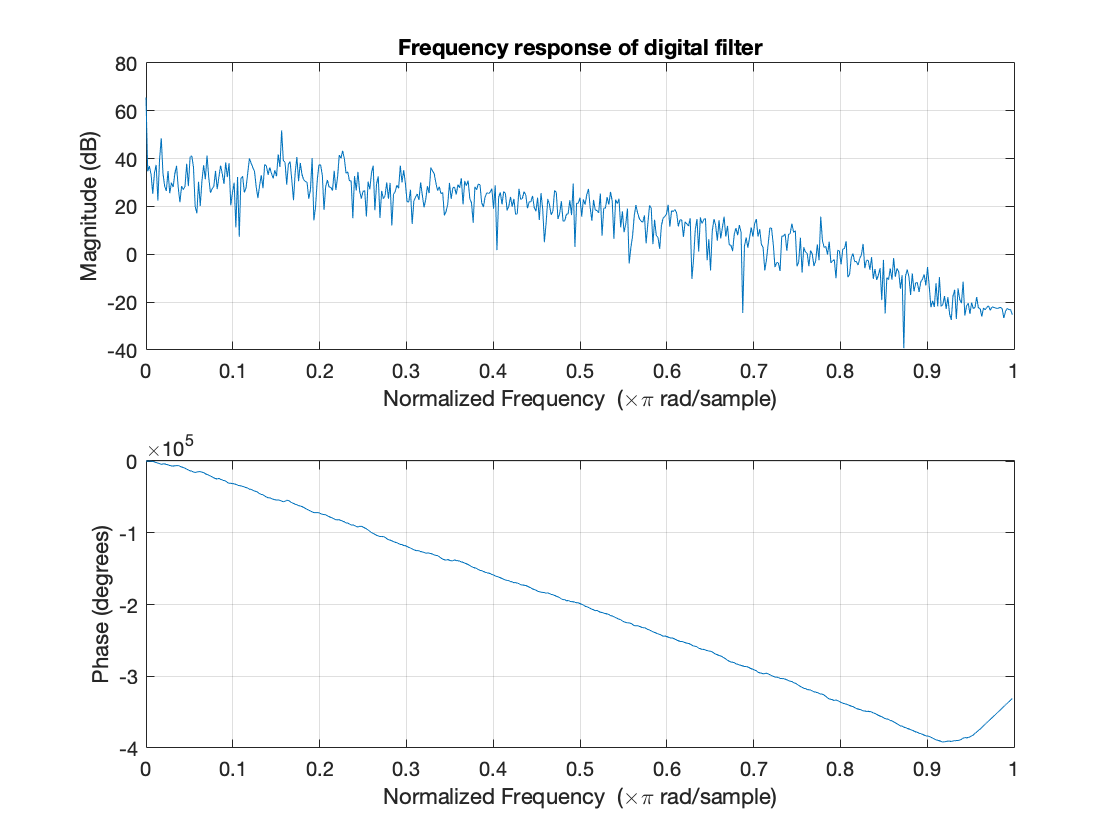


figure;
freqz(y)
title('Frequency response of digital filter')

Question 3.3 IRR and FIR

clear
load('data.mat')

x=d1;
fs=102.4;
f=50;

%calculate normalised frequency
nf=f/fs;
omega=2*pi*nf;

z1=exp(1i*omega);
z2=exp(-1i*omega);

pole1=0.9*exp(1i*omega);
pole2=0.9*exp(-1i*omega);

b=[1,-(z1+z2),z1*z2];

a_fir=1

a_fir = 1

a_iir=[1,-(pole1+pole2),pole1*pole2];

y_fir=filter(b,a_fir,x);
y_iir=filter(b,a_iir,x);

%t = (0:length(y_fir)-1)/fs;
t = (0:length(y_fir)-1)*fs/length(y_fir);

figure(1)
subplot(211)

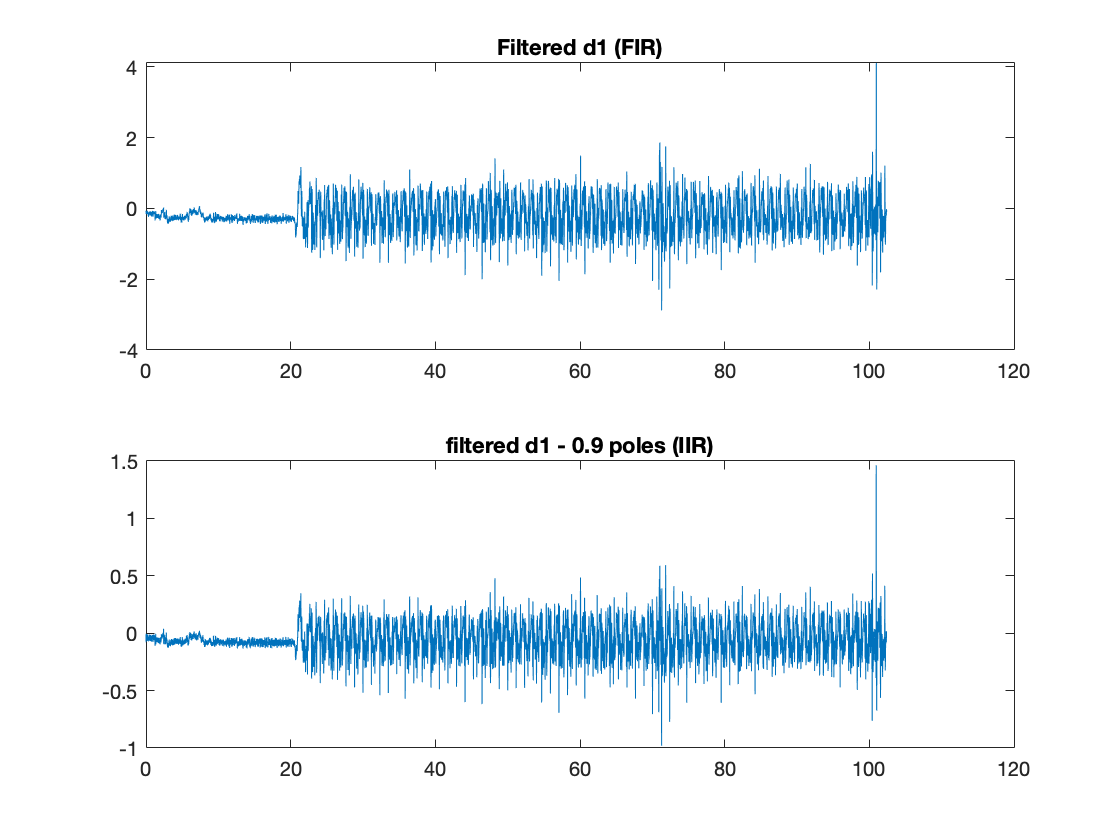

plot(t,y_fir) 
title('Filtered d1 (FIR)');

subplot(212)
plot(t,y_iir)
title('filtered d1 - 0.9 poles (IIR)')

figure(2);
subplot(211)

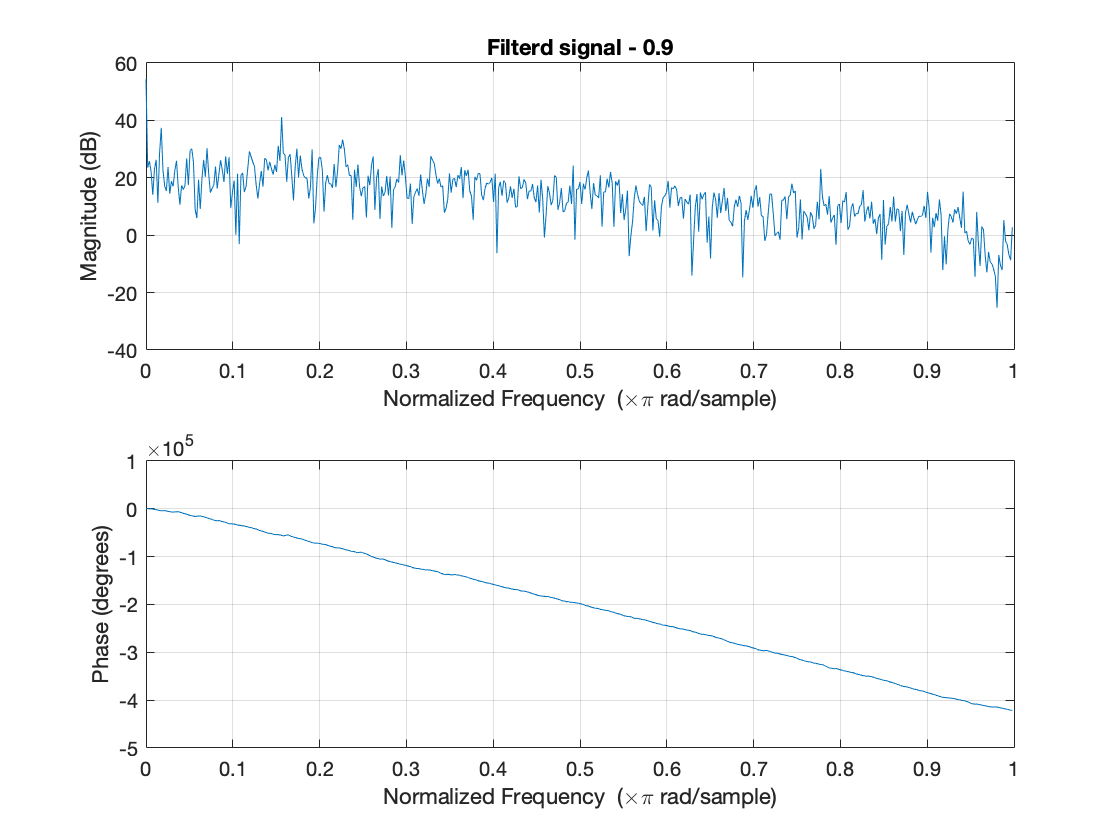

freqz(y_fir)
title('Filterd signal - 1');
subplot(212)
freqz(y_iir)
title('Filterd signal - 0.9');

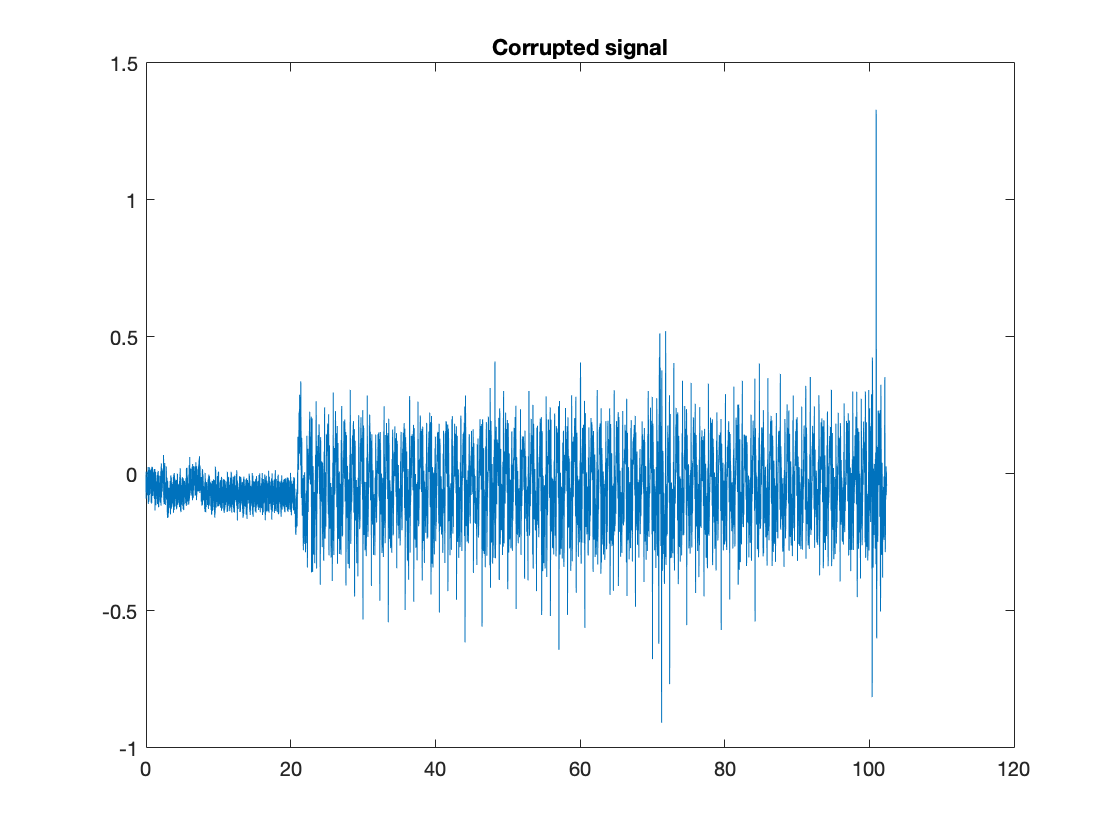


figure;
plot(t,x)
title('Corrupted signal');

Question 3.4

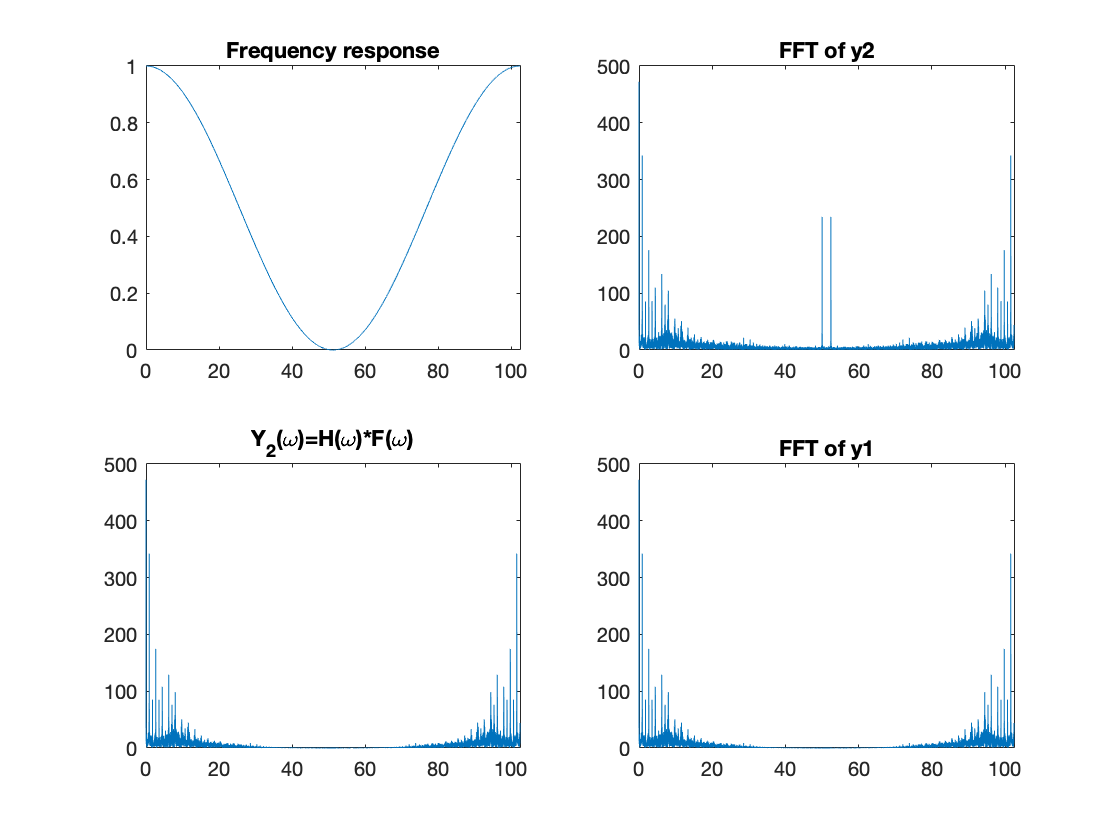

clear
load('data.mat')

h = [0.25, 0.5, 0.25];
a=1;
fs=102.4;

y1 = filter(h,a,d1);

t = ((0:length(y1)-1)*fs)/length(y1);
%t = (0:length(y1)-1)/fs;

%calculating normalised frequency
nf  = (0:length(d1)-1)./length(d1);
omega = 2*pi*nf;

H = 0.25 + 0.5*exp(1i*omega) + 0.25*exp(2i*omega);

F=fft(d1);
H=H';
Y2 = H.*F;

%Y2=0.25*F+0.5*exp(1i*omega)*F+0.25*exp(2i*omega)*F;

Y1=fft(y1);

y2 = real(ifft(Y2));

figure;

subplot(2,2,1);
plot(t,abs(H));
title('Frequency response');

subplot(2,2,2);
plot(t,abs(F));
title('FFT of y2');

subplot(2,2,3);
plot(t,abs(Y2));
title('Y_2(\omega)=H(\omega)*F(\omega)');

subplot(2,2,4);
plot(t,abs(Y1));
title('FFT of y1');

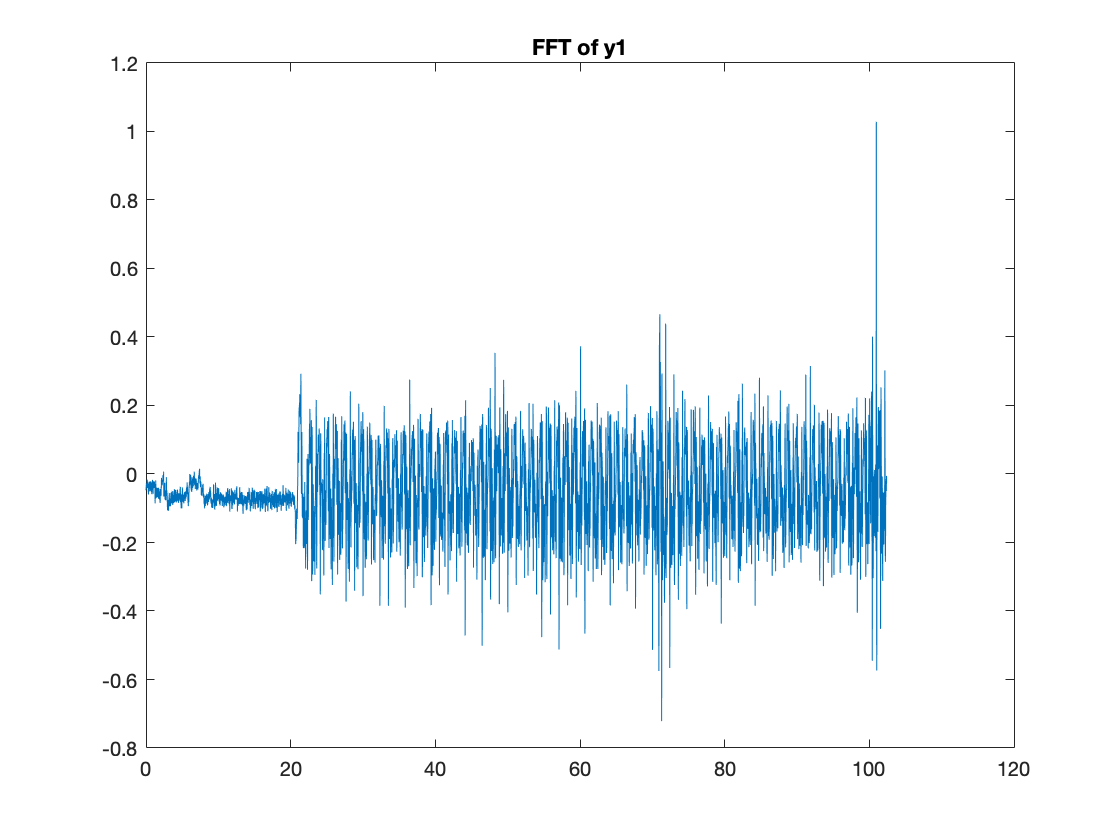


figure
plot(t,y2);
title('FFT of y1');

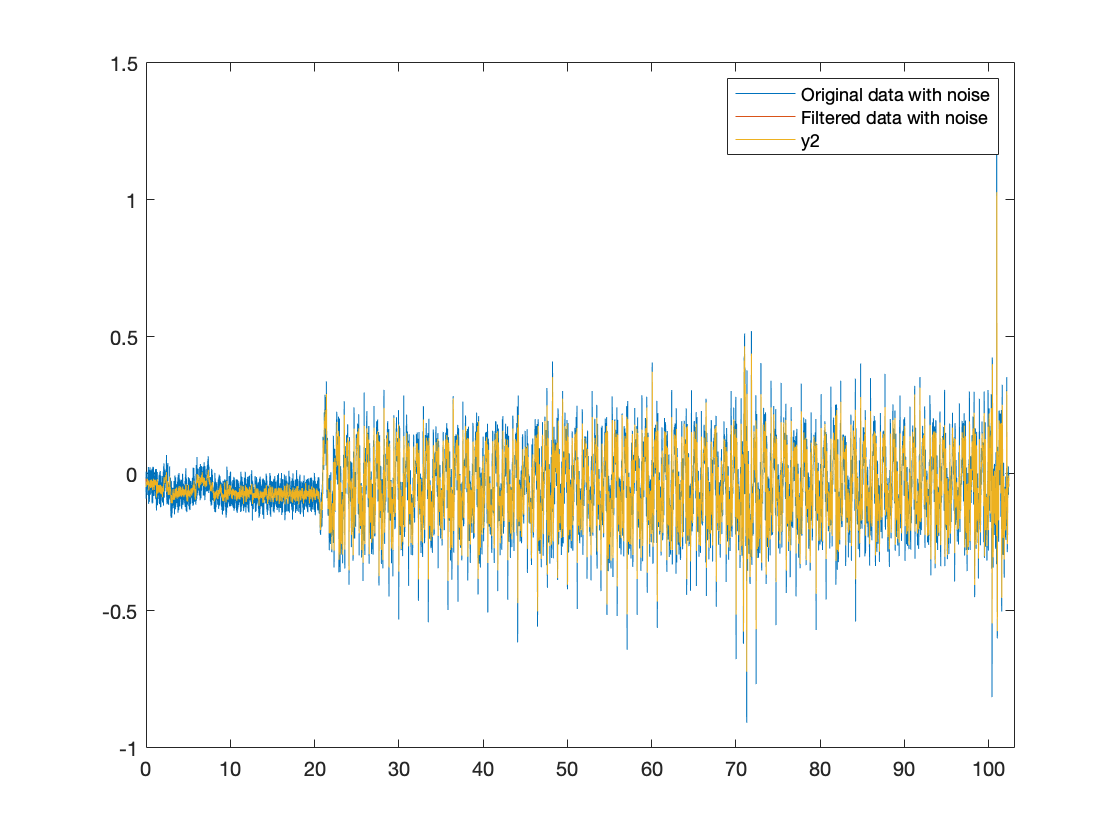


figure;
plot(t,d1,t,y1,t,y2)
legend('Original data with noise','Filtered data with noise','y2');
axis([0,103,-1,1.5]);


mean(abs(y1-y2).^2)

ans = 1.0725e-07

Question 3.5

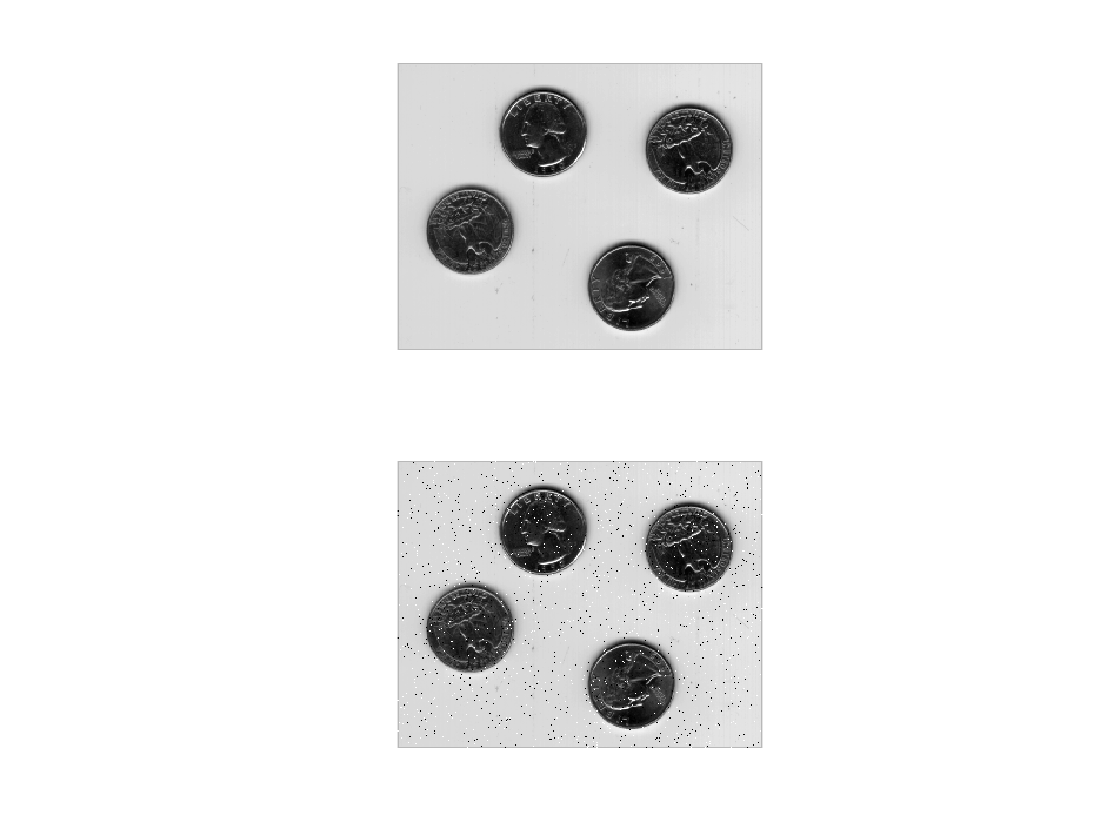

clear

Im = [zeros(5,3),ones(5,2)];
h = ones(3,3);
g = filter2(h,Im);

im1 = imread('eight.tif');
im1=double(im1);

figure;
subplot(2,1,1);
imshow(im1,[]);

im_noise=noise(im1,'sp', 0.02);

subplot(2,1,2);
imshow(im_noise,[]);

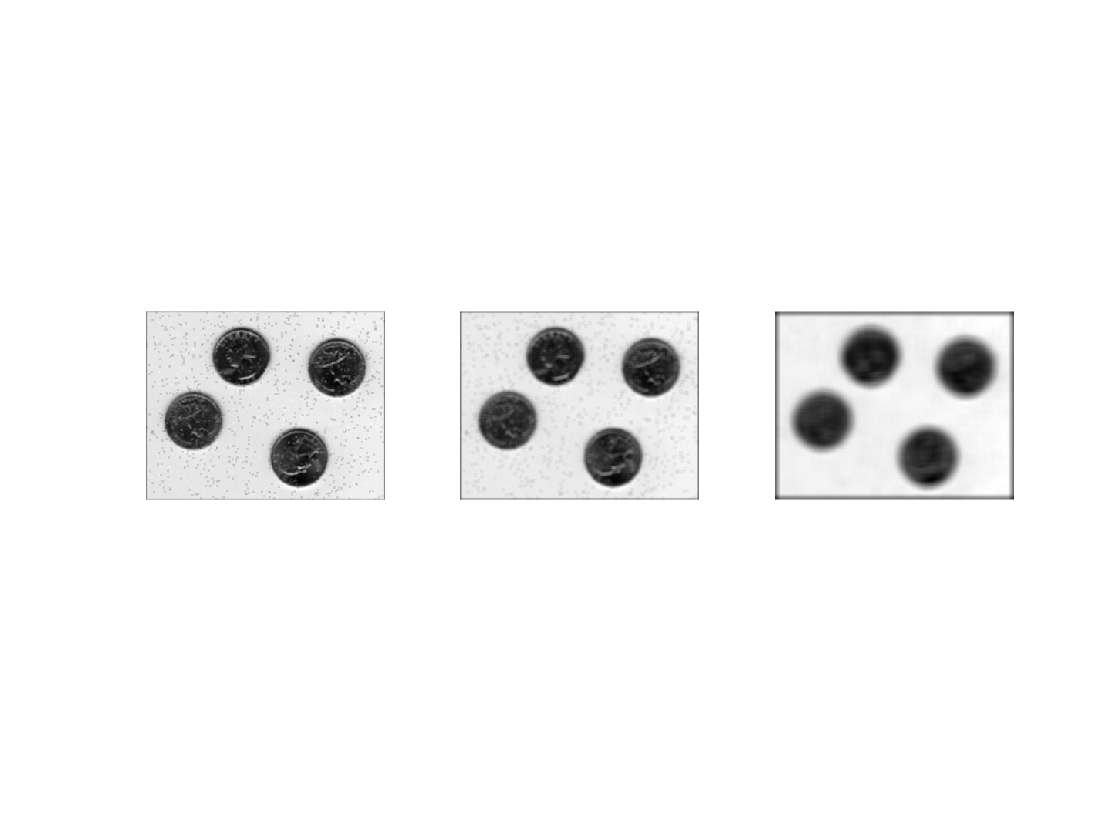


% h3=1/3*ones(3,1);
% h5=1/5*ones(5,1);
% h15=1/15*ones(15,1);
% 
% H3 = h3*h3';
% H5 = h5*h5';
% H15 = h15*h15';

H3 = ones(3,3)/3^2;
H5 = ones(5,5)/5^2;
H15 = ones(15,15)/15^2;

noise_filter3=filter2(H3,im_noise);
noise_filter5=filter2(H5,im_noise);
noise_filter15=filter2(H15,im_noise);

figure;
subplot(1,3,1);
imshow(noise_filter3,[]);
subplot(1,3,2);
imshow(noise_filter5,[]);
subplot(1,3,3);
imshow(noise_filter15,[]);

Question 3.7

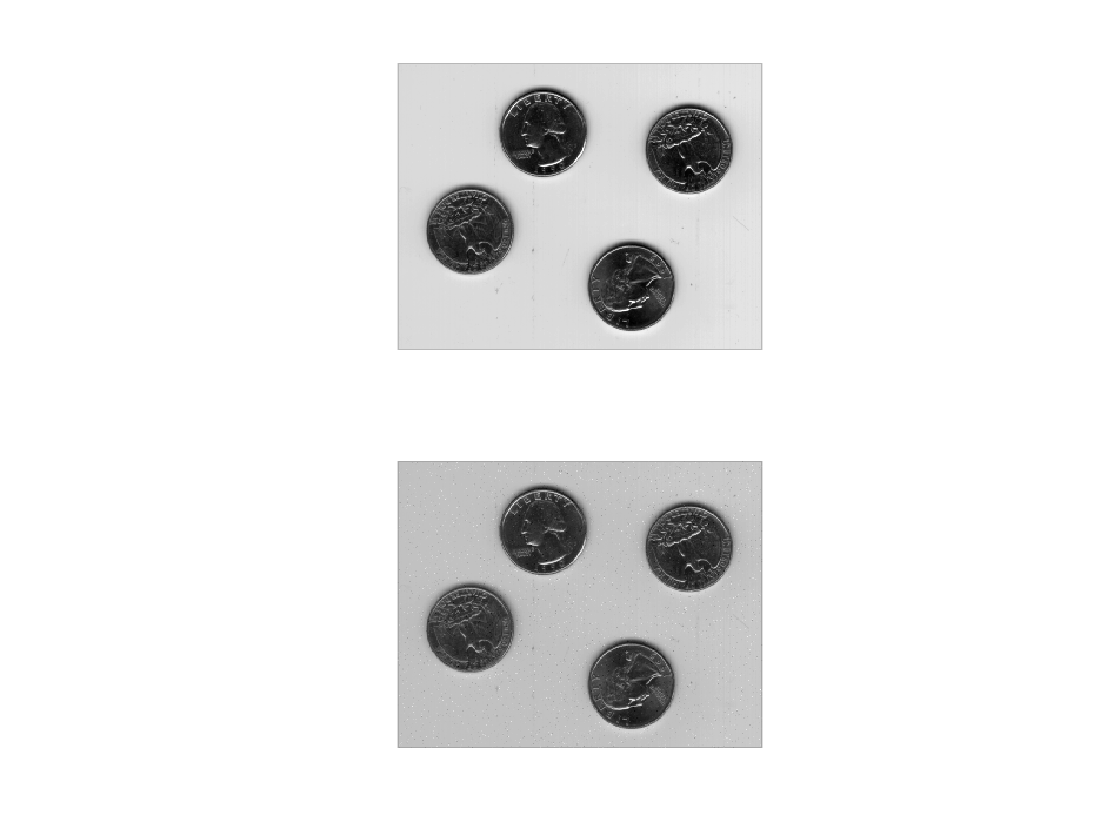

figure;
subplot(2,1,1);
imshow(im1,[]);

im_noise2=noise(im1,'ag',10,0.07);

 subplot(2,1,2);
 imshow(im_noise2,[]);

Question 3.8

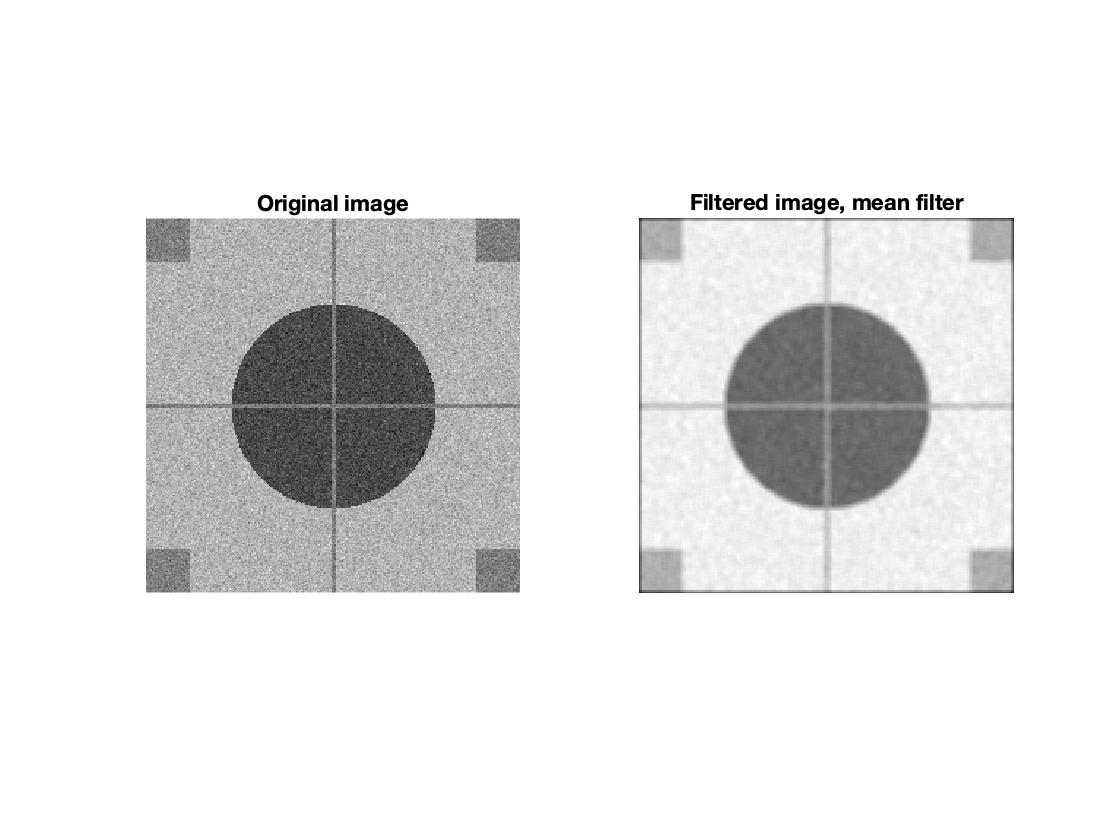

 clear
 
img = imread('circle.bmp');
img=double(img);

fsize = 5;
h = ones(fsize)/fsize^2;

meanim1=filter2(h,img);

figure
subplot(1,2,1);
imshow(img,[]), colormap gray, axis image off;
title('Original image')

subplot(1,2,2);
imshow(meanim1,[]), colormap gray, axis image off;
title('Filtered image, mean filter')

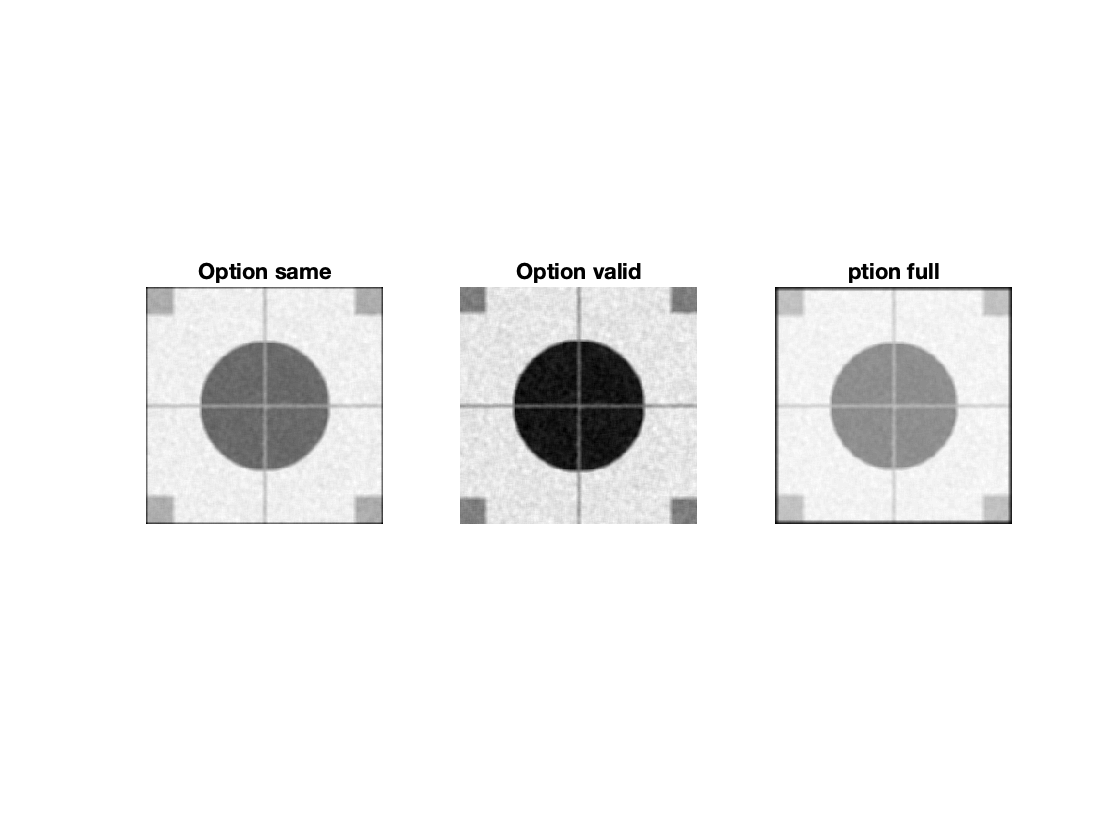


meanim2=filter2(h,img,'same');
meanim3=filter2(h,img,'valid');
meanim4=filter2(h,img,'full');

figure
subplot(1,3,1);
imshow(meanim2,[]), colormap gray, axis image off;
title('Option same')

subplot(1,3,2);
imshow(meanim3,[]), colormap gray, axis image off;
title('Option valid')

subplot(1,3,3);
imshow(meanim4,[]), colormap gray, axis image off;
title('ption full')